%Dimensions of the House
xStart = 0%Ignored Base is ALWAYS (0|0) for Symmetrie Reasons

xStart = 0

yStart = 0

yStart = 0

height = 8

height = 8

width = 8

width = 8

margin = 1

margin = 1



%Door
doorW = 1

doorW = 1

doorH = 2

doorH = 2


%Window
windW = 2;
windH = 2;
windMargin = 0; %0.125

	%Helping Variables
	ww = windW + 2 * windMargin

ww = 2

	wh = windH + 2 * windMargin

wh = 2

	%For House
	rw = width - 2 * margin

rw = 6

	rh = height - margin

rh = 7

    
%Step Size
doorStep = 5

doorStep = 5

windowStep = 2

windowStep = 2



data = 0;

%Steps always begin with 0:step
maxDStep = floor((rw - doorW)/doorStep)

maxDStep = 1

maxWindowStepWidth = floor((rw - ww)/windowStep)

maxWindowStepWidth = 2

maxWindowStepHeight = floor((rh - doorH - wh)/windowStep)

maxWindowStepHeight = 1

maxWStep = maxWindowStepWidth * maxWindowStepHeight %+ maxWindowStepWidth//2

maxWStep = 2


nextPos = floor(ww/windowStep) + 1

nextPos = 2


%Plot
plotSquare(xStart, yStart, width, height,[0 0 0]);
hold on
plotSquare(1,0,6,7,'r'); %Margin
plot(4,4,'go')

%Find all possible configurations
for door = 0:1:maxDStep
    
    for w1 = 0:1:maxWStep
        
        colW1 = mod(w1,maxWindowStepWidth+1)
        rowW1 = floor(w1/maxWindowStepWidth) 
        windX = margin + colW1*(2* windMargin + windW) + windMargin + 0.1 * rand();
        windY = height - margin - (rowW1+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
        

        for w2 = w1+nextPos:1:maxWStep
            colW2 = mod(w2,maxWindowStepHeight+1)
            rowW2 = floor(w2/maxWindowStepHeight)
            windX2 = margin + colW2*(2* windMargin + windW) + windMargin + 0.1 * rand();
            windY2 = height - margin - (rowW2+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
            
            %Plotting
            plotSquare(margin + door * doorStep,yStart, doorX, doorY, [0.5 0.5 0.5]);
            plotSquare(windX, windY, windW, windH, [0.2 1 0.2]);
            plotSquare(windX2, windY2, windW, windH, [0.4 0.5 0]);  
            
            
            axis equal;
            data = data + 1;
        end
    end
end

colW1 = 0

rowW1 = 0

colW2 = 0

rowW2 = 2

colW1 = 1

rowW1 = 0

colW1 = 2

rowW1 = 1

colW1 = 0

rowW1 = 0

colW2 = 0

rowW2 = 2

colW1 = 1

rowW1 = 0

colW1 = 2

rowW1 = 1

data

data = 2

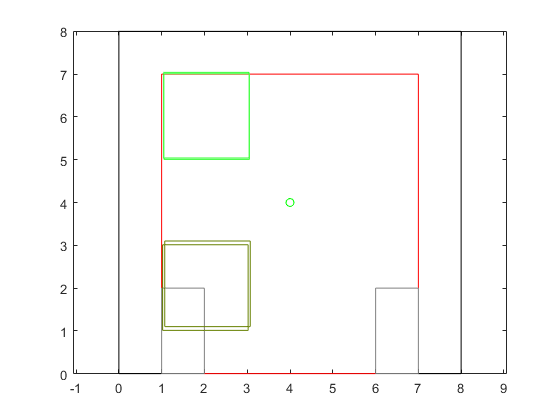

hold off

*IF, door,LE,3,THEN

	*IF, w1, GE, 12, THEN

	colW1 = colW1 + 2

	*ELSE

	*ENDIF

	!Same for w2

	*IF, w2, GE, 12, THEN

	colW2 = colW2 + 2

	*ELSE

	*ELSE

	*ENDIF